# MATLAB Assignment 1 - Farfield evaluation using SGF

# **Farfield evaluated using SGF**

## **Theory**

The electric field radiated by an electric current can be expressed as follows:

when considering stationary phase point, the farfield can be evaluated asmptotically:

where $\left(x^{\prime } ,y^{\prime } ,z^{\prime } \right)$is the source position while $\left(x,y,z\right)$ is the observation position, $k_{\textrm{xs}} =k\sin \theta \cos \phi ,k_{\textrm{ys}} =k\sin \theta \sin \phi ,k_{\textrm{zs}} =k\cos \theta \;$rerepresent the dominant plane wave,$\overrightarrow{J} \left(k_x ,k_y \right)$ is the FT of the current distribution, and ${\tilde{G} }^{\textrm{ej}}$ is the dyadic SGF for electric currents ($+k_{z\;}$only for $z>0$):

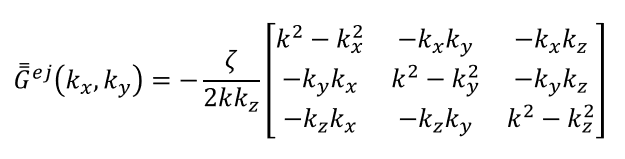

**Directivity**

The directivity of a farfield can be obtained as:

where $U\left(\theta ,\phi \right)$ is the radiation intensity:

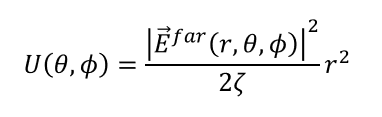

and $P_{\textrm{rad}}$ is the total radiated power:

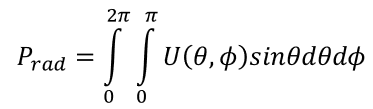

## MATLAB Implementation

To evaluate the farfield radiated by a current, we should perform the following steps:

**(1)** Calculate the dyadic SGF. **(2)** Obtain the FT of the current distribution. **(3)** Using the dyadic SGF and FT of the current distrubution, evaluate the farfield. **(4) **Estimate the directivity of the farfield.

The above steps are applicable for any source so it would be convenient to build separate routines for these steps, and then reuse it for different applications. Today you should learn how to build the routines:

**(1)**  [ej_SGF] = **EJ_SGF**(er, k, kx, ky)

**(2)** Jx = **FTCurrent**(k, er, kx, ky, l, w)

**(3)** [Eth, Eph] = **farfield**(k, R_FF, TH, PH, kz, Gxx, Gyx, Gzx, Jx)

**(4)** [Dir, Prad] = **Directivity**(E_tot, Theta, dth, dph, er, r)

# Q1 (3 points): Elementary electric source

Write a Matlab routine to calculate the free space *Spectral Green’s Function* (SGF) of an elementary electric source oriented along x and placed at the origin.

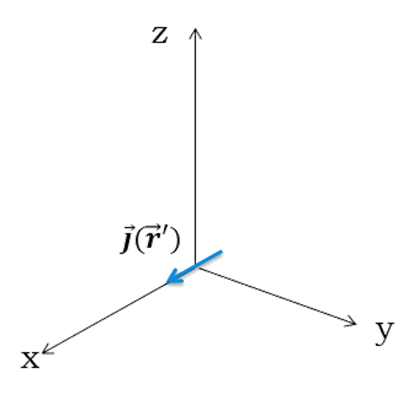

### 1. Plot the x- and y-components of the SGF. 

Both real and imaginary parts should be plotted. Consider$f=30$ GHz, $k_x \in \left\lbrack 0,3k_0 \right\rbrack$ and $k_y =0$. 

**Routines to calculate SGF**

It would be conveninent to write a routine to calculate the complete SGF for electric currents: 

[ej_SGF] = **EJ_SGF**(er, k, kx, ky)

Note that $k_z$ should be defined uniquely as follows:

**Elementary source in free space**

In this case,$\overrightarrow{j} \left(x,y,z\right)=\delta \left(x\right)\delta \left(y\right)\delta \left(z\right)\hat{x}$, and its FT is $\overrightarrow{J} \left(k_x ,k_y \right)=\hat{x}$.

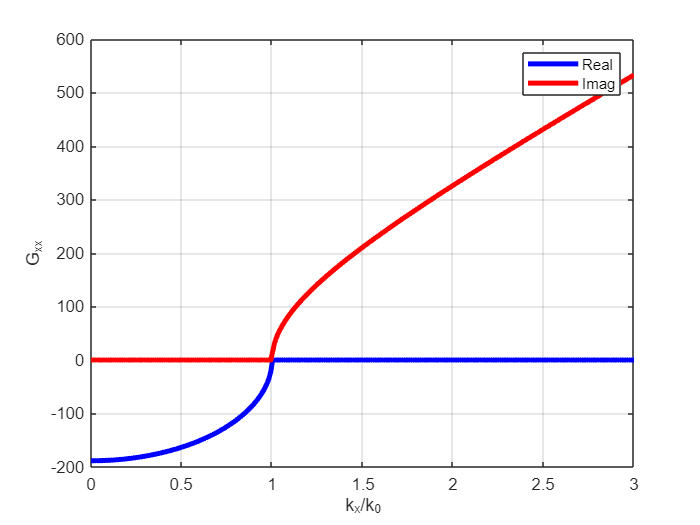

clc
clear all
close all

% Constant
er = 1;

% Freq. dependent
f  = 30e9;
lambda = 3e8 / f;
k0 = 2 * pi / lambda;

% FF parameters
num_kx = 300;
kx = k0 * linspace(eps, 3, num_kx);
ky = zeros(size(kx));
[ KX, KY ] = meshgrid(kx, ky);

% calculate voltages and currents
ej_SGF = EJ_SGF(er, k0, KX, KY);
Gxx = ej_SGF(1,:,1,1);
Gyy = ej_SGF(1,:,2,2);

% Gxx
figure
plot(kx / k0, real(Gxx),'color', 'b', 'linewidth', 3);
hold on
plot(kx / k0, imag(Gxx),'color', 'r', 'linewidth', 3);
grid on
xlabel('k_x/k_0')
ylabel('G_{xx}')
legend('Real', 'Imag')

### **2. In which region of the spectrum is the x-component imaginary?**

# Q2 (4 points): Farfield of a dipole

Write a Matlab program to calculate the far field radiated by the printed dipole shown in the figure using the free space SGF. (upper sphere)

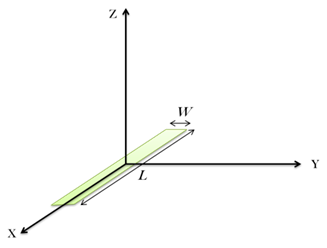

### 1. 1D plot of the farfield in main planes

Consider a dipole: $L=\lambda_0 /2,w=\lambda_0 /40$ @ 30 GHz, and calculate the far field (total field) in $\phi =0^{\circ \;} /{{45}^{\circ \;} /90}^{\circ \;}$ planes.

**Farfield evaluated using SGF**

**Step 1:  Calculate the dyadic SGF**

Build the dyad for electric current: [ej_SGF] = **EJ_SGF**(er, k, kx, ky)

% calculate voltages and currents
ej_SGF = EJ_SGF(er, k0, KX, KY);

**Step 2:  Calculate the FT of the current distribution**

For dipole antennas, we can approximate the spatial current distribution using the current distribution along an open circuited transmission line. This distribution can be expressed in general as follows:

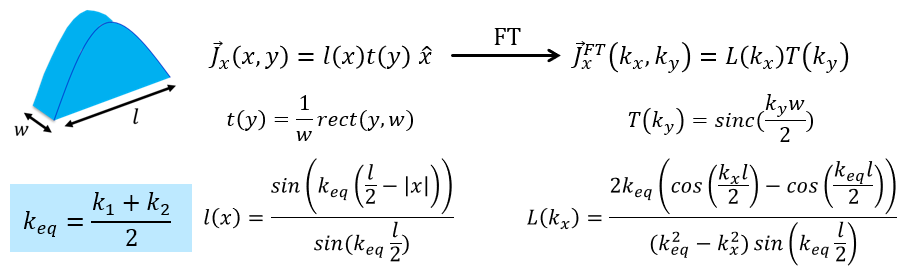

Write a routine to calculate the FT of currents: Jx = **FTCurrent**(k0, er, kx, ky, l, w)

% calculate FT of current distribution
L = lambda/2;
W = lambda/40;
Jx = FTCurrent(k0, er, KX, KY, L, W);
J = Jx;
Jx = Jx(1, :);

**Step 3:  Evaluate the farfield (total field)** 

Calculate the FF in Eth and Eph and plot the total field: 

[Eth, Eph] = **farfield**(k0, R_FF, TH, PH, Gxx, Gyx, Gzx, Jx, kz, z)

% calculate far field
KZ = -1j * sqrt( -(k0^2 - kx.^2 - ky.^2) );

R_FF = linspace(eps, 5, num_kx);
th = linspace(eps, pi / 2, num_kx);
ph = linspace(eps, pi * 2, num_kx);
[ TH, PH ] = meshgrid(th, ph);

E = farfield(k0, R_FF, TH, PH, KZ, ej_SGF, J);
Eth = E(:, :, 2);
Eph = E(:, :, 3);

E_tot = sqrt(abs(Eth).^2 + abs(Eph).^2);

### 2. Farfield in the upper medium (z>0) plotted using UV representation 

In UV plane: $U=\sin \theta \;\cos \phi ,V=\sin \theta \;\sin \phi$. Here we use a dynamic range of 10 dB.

% plot result
U = sin(TH) .* cos(PH);
V = sin(TH) .* sin(PH);

### 3. Evaluated the directivity at broadside in dB as a funciton of frequency 

Calculate the FF as a function of frequency and evaluate the directivity for each frequency. The dipole dimensions are: $L=\lambda_0 /2,w=\lambda_0 /40$ @ 30 GHz

**Directivity**

The directivity of a farfield can be obtained as:

where $U\left(\theta ,\phi \right)$ is the radiation intensity:

and $P_{\textrm{rad}}$ is the total radiated power:

We can build a routine to calculate the directivity: [Dir, Prad] = **Directivity**(E_tot, Theta, dth, dph, er, r)

[Dir(ff), ~] = Directivity(E_tot_abs, TH, dth, dph, er, R_FF);

# Q3 (3 points): Dipole with backing reflector

Consider a dipole: $L=\lambda_0 /2,w=\lambda_0 /40$ @ 30 GHz, that is radiating in the presence of an infinite PEC plane as shown in the figure.

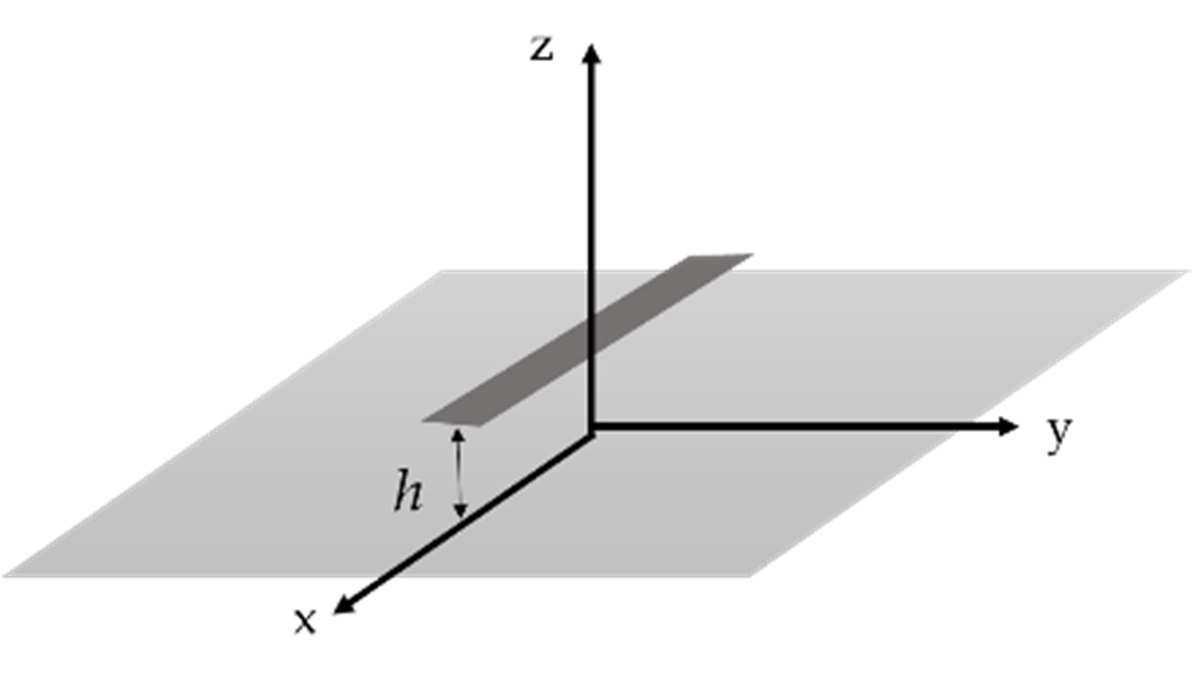

### 1. Plot 1D farfield along the main planes and compare it to the one in Q2.

Here we consider $h=7\ldotp 5$ mm. To remove the PEC plane and use free space's GF, we can resort to image therom. 

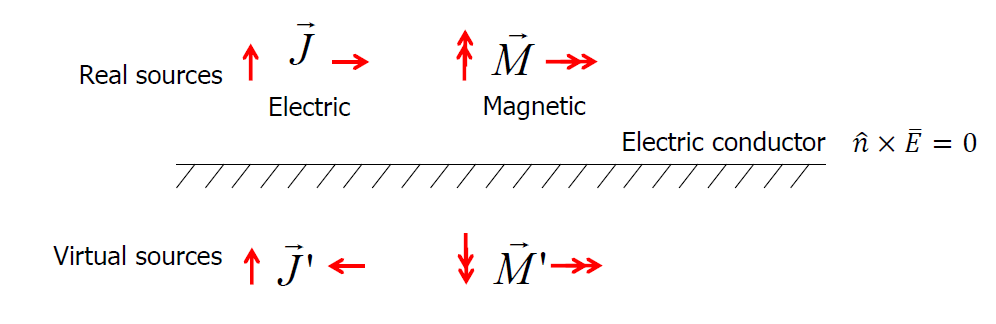

In our case, the eletric current is horizontal. Therefore, we can remove the PEC and place an image current at $z=-h$ with the opposite direction. The total current can then be expressed as:

The FT of the total current will be similar to previous one, but with an additional term $2j\;\sin \left(k_z h\right)$.

**Step 1:  Calculate the dyadic SGF**

**Step 2:  Calculate the FT of the current distribution**

**Step 3:  Evaluate the far field (total field)**

### 2. Evaluate the directivity at broadside (linear) as a funciton of the source height h 

Calculate the FF as a function of $h$ and evaluate the directivity for each $h$. 

**Note: A report should accompany the figures and results to provide necessary explanations. **